clear all;
close all;
clc;

n=[10, 50, 100, 250, 500];   % we will show how b, s^2, and Varhat(bhat) evolve as we increase the sample size.
k=3;
result1=zeros(k+1,length(n));
result2=zeros(1,length(n));
result3=zeros(k+1,length(n));

beta=[1,2,3,4]';     % \beta: true parameter values that are unknown to the econometrician.

for i=1:length(n);
    eps=zeros(n(i),1);   
    x=zeros(n(i),k);
    
    
    eps=randn(n(i),1);   %drawing n(i)x1 random vectors  from the standard normal distribution.
    
    for j=1:k;
        
        x(:,j)=randn(n(i),1);  %We also generate n(i)xk random matrix of X from the standard normal distribution.
    end
   x=[ones(n(i),1),x];         %We also add the constant by including the vector of ones.
   
   y=zeros(n(i),1);
   
   y=x*beta+eps;              %We generate the true model where y=X*\beta+\epsilon
   
   b=inv(x'*x)*x'*y           %We estimate the true model by the OLS estimator.
   s2=((y-x*b)'*(y-x*b)/(n(i)-k))              %We estimate \sigma^{2}. Note that epsilon ~ N(0, I_{n}), therefore \sigma^2=1.
   varbhat=s2*inv(x'*x)                        %Estimated variance for the variance of the OLS estimator.
   result1(:,i)=b;
   result2(:,i)=s2;
   result3(:,i)=diag(varbhat);
 
end

b =     0.6824
    2.3047
    3.9426
    4.6546


s2 = 0.8164

varbhat =     0.1723   -0.1252   -0.1989   -0.0910
   -0.1252    0.1980    0.2062    0.0587
   -0.1989    0.2062    0.6562    0.3218
   -0.0910    0.0587    0.3218    0.3855


b =     1.1454
    2.1564
    3.0124
    3.8865


s2 = 1.3394

varbhat =     0.0273   -0.0013    0.0030    0.0024
   -0.0013    0.0280    0.0031    0.0005
    0.0030    0.0031    0.0257    0.0024
    0.0024    0.0005    0.0024    0.0438


b =     1.1526
    1.9788
    3.0077
    4.0333


s2 = 0.8926

varbhat =     0.0100   -0.0005    0.0004    0.0034
   -0.0005    0.0097    0.0002   -0.0011
    0.0004    0.0002    0.0091    0.0006
    0.0034   -0.0011    0.0006    0.0114


b =     0.9537
    1.9209
    2.9841
    3.9884


s2 = 1.0237

varbhat =     0.0041   -0.0001    0.0002   -0.0001
   -0.0001    0.0047    0.0002    0.0001
    0.0002    0.0002    0.0040    0.0000
   -0.0001    0.0001    0.0000    0.0037


b =     0.9681
    1.9991
    2.9141
    4.0066


s2 = 0.9285

varbhat =     0.0019    0.0000   -0.0000    0.0001
    0.0000    0.0021    0.0001    0.0000
   -0.0000    0.0001    0.0020   -0.0002
    0.0001    0.0000   -0.0002    0.0019


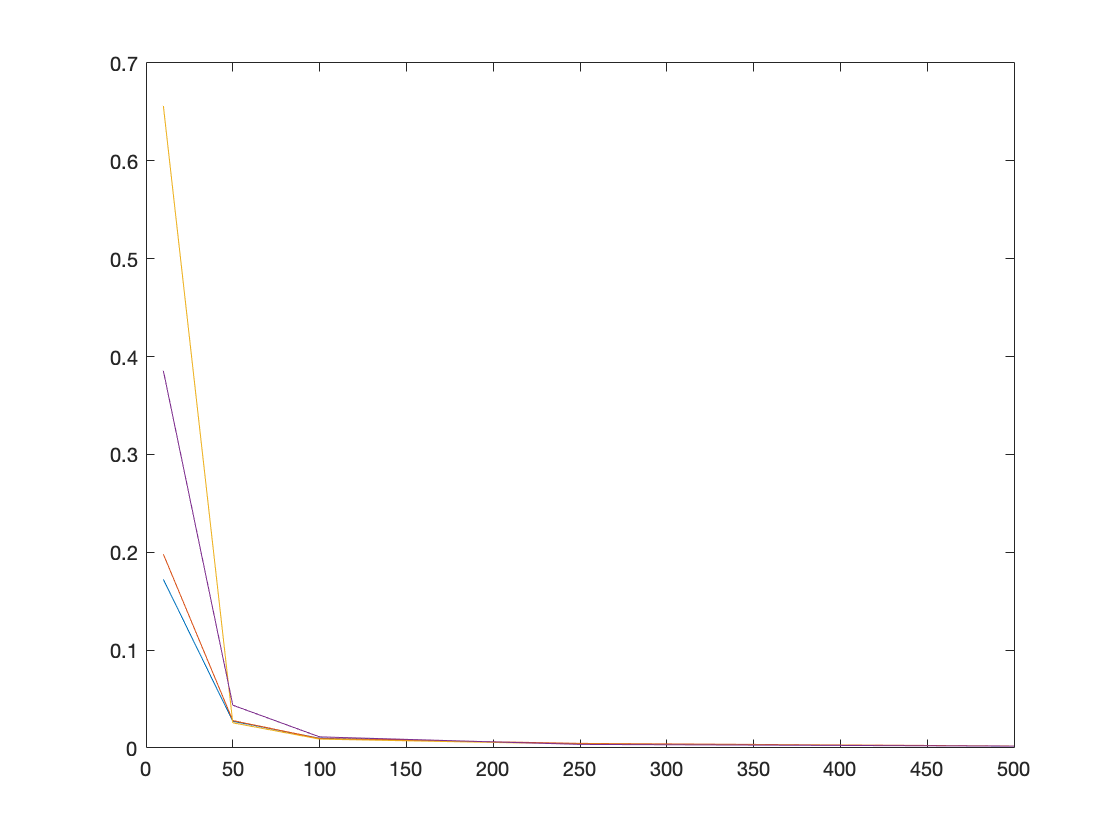

% 
% plot(n,result1(1,:))
% hold all
% plot(n,result1(2,:))
% hold all
% plot(n,result1(3,:))
% hold all
% plot(n,result1(4,:))

%% Uncomment these after saving the above figure

% plot(n,result2(1,:))
% 
% 
% 
plot(n,result3(1,:))
hold all
plot(n,result3(2,:))
hold all
plot(n,result3(3,:))
hold all
plot(n,result3(4,:))

% % 

%% Your assignment: Think about this simulation and how it is related to the module material. 
% You might want to increase the number of observations to see what happens
% to the parameters asymptotically.